# Regulatorer.

***This is a compendium of a variety of regulators.***

***Made by me during my engineering degree.***

***This is meant to be open for all whom would need it, expansion and contributions are welcomed, if so, and done cleanly and well documented. pleas push request the repository.***

**copr. 2021 Sverre Kvist. All rights reserved**

***Contributors:***

#### Transfer function.

clc, clear, close all;
FuncType="PoleZeroTIdsforsinkelse";

**Fields under are defined by wich function type is chosen.**

nom=[ ]; denom=[-1 -10]; k=50; tau=5;
 
switch FuncType
    case 'Polynom'                                      %Lager ein transferfunksjon av polynom.
        Gs = k*tf(nom, denom)
        or = zpk(Gs)
    case 'PoleZero'                                     %Lager ein transferfunksjon av Poles&Zeroes
        Gs=zpk([nom], [denom], k)
        or=tf(Gs)
    case 'PolynomTIdsforsinkelse'                       %Lager ein transferfunksjon av polynom med tidsforsinkelse.
        Gs = tf(nom,denom,'InputDelay',tau)
        [nom,denom] = pade(tau,1);
        tidsforsinkelse_som_polynom = tf(nom,denom)     %konverterer exponentialform til polynomform
        Gs_med_tidsforsinkelse = tidsforsinkelse_som_polynom*tf(nom,denom)      %funksjon med tidsforsinkelse

    case 'PoleZeroTidsforsinkelse'                      %Lager ein transferfunksjon av Poles&Zeroes med tidsforsinkelse.
       Gs=zpk([nom], [denom], k,'InputDelay',tau)
       disp('Omskrivning av tidsforsinkelse til polynomform.')
       [nom,denom] = pade(tau,1);
       tidsforsinkelse_som_polynom = tf(nom,denom)      %konverterer exponentialform til polynomform
       Gs_med_tidsforsinkelse = tidsforsinkelse_som_polynom*tf(nom,denom)       %funksjon med tidsforsinkelse
    case 'Empty'

end

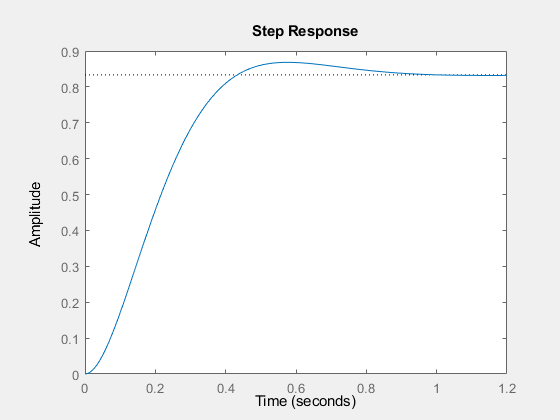

type_plott = "Step_feedback";
 
close all;
switch type_plott
    case'Bode'
        
        figure('Name',' Bode Diagram av Transferfunksjon');
        bode(Gs);
        set(gcf,'Visible','on');
    case'Bode_marginer'
        figure('Name',' Bode Diagram av Transferfunksjon med marginer');
        margin(Gs);
        set(gcf,'Visible','on');
    case'Step'
        figure('Name',' Step Respons av transferfunksjon.');
        stepResponse = stepplot(Gs);
        grid minor; 
        set(gcf,'Visible','on');
    case'Step_feedback'
        figure('Name',' Step Respons med Feedback');
        step(feedback(Gs,1));
        set(gcf,'Visible','on');
end


$$\begin{array}{l}
\mathrm{Find}\;\mathrm{phase}\;\mathrm{in}\;\;\mathrm{bode}\;\mathrm{plott}\;\mathrm{from}\;\mathrm{regulator}\;\mathrm{with}\;\mathrm{table}:\\
\left\lbrack \begin{array}{ccccc}
 & P & \mathrm{PI} & \mathrm{PD} & \mathrm{PID}\\
\omega {\;}_{\o c}  & \mathrm{PM}-{180}^{\circ }  & \mathrm{PM}-{160}^{\circ }  & \mathrm{PM}-{220}^{\circ }  & \mathrm{PM}-{200}^{\circ } \\
 &  &  &  & \\
T_i  &  & \frac{2\ldotp 8}{\omega {\;}_{\o c} } &  & \frac{2\ldotp 8}{\omega {\;}_{\o c} }\\
T_d  &  &  & \frac{1}{\omega {\;}_{\o c} } & \frac{1}{\omega {\;}_{\o c} }\\
K_p \left\lbrack \mathrm{dB}\right\rbrack  & \;\;-|G_p \left(j\omega \right)H\left(j\omega {\;}_{\o c} \right)|\;\;\; & \;\;\;\;\;-|G_p \left(j\omega \right)H\left(j\omega {\;}_{\o c} \right)|-1\mathrm{dB}\;\;\;\;\;\;\;\;\;\;\;\; & -|G_p \left(j\omega \right)H\left(j\omega {\;}_{\o c} \right)|-3\mathrm{dB}\;\;\;\;\;\;\;\;\;\;\;\; & \;\;\;-|G_p \left(j\omega \right)H\left(j\omega {\;}_{\o c} \right)|-4\mathrm{dB}
\end{array}\right\rbrack 
\end{array}$$



$$\begin{array}{l}
\omega {\;}_{\phi C} \Rightarrow \textrm{rad}/s\\
K_{p\;} \left\lbrack \textrm{dB}\right\rbrack \Rightarrow \textrm{dB}
\end{array}$$


omega = 1.23; dB =    0.504;
 

#### PID-kontrollere ved frekvensrespons

Regulator="P-kontroller";
 
switch Regulator
    case 'P-kontroller'
        disp('P-kontroller')
        kp=10^(-dB/20);
        Gc = tf(kp)
        as_zpk = zpk(Gc)
        clear kp;
    case 'PI-kontroller'
        disp('PI-kontroller')
        kp = 10^((-(dB)-1)/20);
        ti = 2.8/omega;
        Gc = kp*tf([ti 1],[ti 0])
        as_zpk = zpk(Gc)
        clear kp ti;
    case 'PD-kontroller'
        disp('PD-kontroller')
        kp = 10^((-(dB)-3)/20);
        td = 1/omega;
        Gc=kp*tf([td 1],[0.1*td 1])
        as_zpk = zpk(Gc)
        clear kp td;
    case 'PID-kontroller'
        disp('PID-kontroller')
        kp = 10^((-(dB)-4)/20);
        ti = 2.8/omega;
        td = 1/omega;
        Gc = kp*tf([ti 1],[ti 0])*tf([td 1],[0.1*td 1])
        as_zpk = zpk(Gc)
        clear kp ti td;
     case 'Empty'
end

P-kontroller


Gc =
 
  0.9436
 
Static gain.



as_zpk =
 
  0.94363
 
Static gain.



#### PID-Controller by Ziegler Nichol's method

GM=29.3; wk=0;
 
kk=10^(GM/20)

kk = 29.1743

Tk=(2*pi)/wk

Tk = Inf

Regulator="P-kontroller";

switch Regulator
    case 'P-kontroller'
        disp('P-kontroller')
        kp=0.5*kk;
        Gc = tf(kp)
        as_zpk = zpk(Gc)
        clear kp;
    case 'PI-kontroller'
        disp('PI-kontroller')
        kp = .45*kk;
        ti = 0.85*Tk;
        Gc = kp*tf([ti 1],[ti 0])
        as_zpk = zpk(Gc)
        clear kp ti;
    case 'PD-kontroller'
        disp('PD-kontroller')
        kp = .65*kk;
        td = .12*Tk;
        Gc=kp*tf([td 1],[0.1*td 1])
        as_zpk = zpk(Gc)
        clear kp td;
    case 'PID-kontroller'
        disp('PID-kontroller')
        kp = .65*kk;
        ti = .5*Tk;
        td = .12*Tk;
        Gc = kp*tf([ti 1],[ti 0])*tf([td 1],[0.1*td 1])
        as_zpk = zpk(Gc)
        clear kp ti td;
    case 'Empty'
end

P-kontroller


Gc =
 
  14.59
 
Static gain.



as_zpk =
 
  14.587
 
Static gain.



#### System with controller and plot.

systemfunksjon med kontrollet integrert


Gtot =
 
      14.59 s + 145.9
  -----------------------
  s^3 + 7 s^2 + 19 s + 45
 
Continuous-time transfer function.



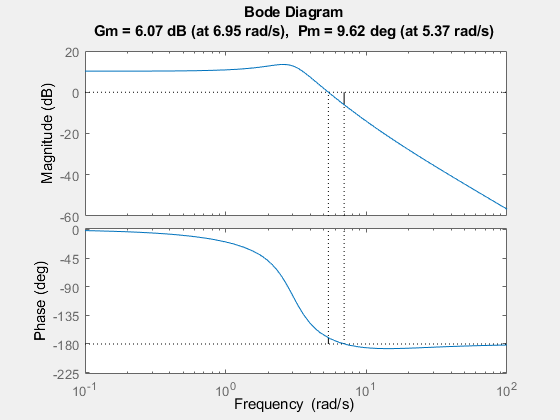

clc, close all; clearvars -except Gs Gc as_zpk
Plott = "Bode";
 
switch Plott
    case 'Step'
        disp('systemfunksjon med kontrollet integrert')
        Gtot = Gs*Gc                                                            %Funksjon med kontroller koblet til.
            figure('Name','Step-Respons med feedback av kontrollert system');
                stepResponse = stepplot(feedback(Gtot,1)); grid minor;
                set(gcf,'Visible','on');
    case 'Ramp'
        disp('systemfunksjon med kontrollet integrert')
        Gtot = Gs*Gc                                                            %Funksjon med kontroller koblet til.
        %figure('Name','Ramp-Respons med feedback av kontrollert system');
        %s = tf('s');
        kv=dcgain(Gtot*tf([1 0],1))
        statisk_feil=1/kv
        %G_rampe =Gtot/s;
        %step(feedback(G_rampe,1)); 
        %grid minor;
        set(gcf,'Visible','on');
    case 'Parabola'
        disp('systemfunction with integrated controller')
        Gtot = Gs*Gc                                                            %Funksjon med kontroller koblet til.
            figure('Name',' Parabola-diagram of system with integrated controller');
                step(feedback(Gtot,1)/s^2); grid minor;
                set(gcf,'Visible','on');
    case 'Bode'
        disp('systemfunksjon med kontrollet integrert')
        Gtot = Gs*Gc                                                            %Funksjon med kontroller koblet til.
            figure('Name',' Bode-diagram of system with integrated controller');
                margin(Gtot);
                set(gcf,'Visible','on');
    case 'Empty'
    
end

#### Steady-state error.

clc, close all; clearvars -except Gs Gc as_zpk
step="step";
 
switch step
    case 'ramp'
        Gtot = Gs*Gc; %Funksjon med kontroller koblet til.
        kv=dcgain(Gtot*tf([1 0],1));
        statisk_feil=1/kv
    case 'step'
        Gtot = Gs*Gc; %Funksjon med kontroller koblet til.
        statisk_feil = dcgain(Gtot)
    case 'Empty'

end

statisk_feil = Inf

#### Lead-Regulator

clc, close all, clearvars -except Gs Gc;
syms B
pol_1 = -30; pol_2 = -10; pol_3 = -1;
pol_ny = -8-9i; nullpunkt = -9; k= 1

k = 1

 
real_1=real(pol_1);                 %Extract real-part of pole #1
real_2=real(pol_2);                 %Extract real-part of pole #2
real_3=real(pol_3);                 %Extract real-part of pole #3
real_ny=real(pol_ny);               %Extract real-part of wanted pole
imag_1 = imag(pol_1);               %Extract imaginary part of pole #1
imag_2 = imag(pol_2);               %Extract imaginary part of pole #2
imag_3 = imag(pol_3);               %Extract imaginary part of pole #3
imag_ny = imag(pol_ny);             %Extract imaginary part of wanted pole
%  IF A POLE IS TO THE LEFT OF THE NEW POLE, THE EQUATION WITH
% THE RESPECTIVE POLE HAVE : 180-[RESPECTIVE EQUATION]
% EXAMPLE: vinkel_3 = 180- abs( rad2deg(atan( imag_ny / (abs( real_3-real_ny )) )) )

vinkel_1 = (abs(rad2deg(atan( abs(imag_ny) / (abs( real_1 - real_ny )) )) ))    %CALCULATE ANGLE BETWEEN NEW POLE AND POLE #1

vinkel_1 = 22.2490

vinkel_2 = (abs(rad2deg(atan( abs( imag_ny ) / (real_2 - real_ny) )) ))         %rekna vinkel mellom ny pol og pol #2

vinkel_2 = 77.4712

vinkel_3 = 180-(abs(rad2deg(atan( imag_ny / (real_3-real_ny) )) ))              %rekna vinkel mellom ny pol og pol #3

vinkel_3 = 127.8750

regulator_bidrag = -180 +vinkel_1+vinkel_2+vinkel_3                             %rekna kva lead-regulator må bidra med

regulator_bidrag = 47.5952

vinkel_n = abs(rad2deg(atan( imag_ny/ abs(real_ny-nullpunkt)) ))

vinkel_n = 83.6598

NyPol_bidrag = regulator_bidrag-vinkel_n;
nevnar =tan(abs(deg2rad(NyPol_bidrag)));
tellar = abs(imag_ny) + abs(real_ny)*tan(abs(deg2rad(NyPol_bidrag)));
b = tellar / nevnar

b = 20.3581

G_Lead=zpk([nullpunkt],[-b],k)             % add value to transfer function for regulator

G_Lead =
 
    (s+9)
  ---------
  (s+20.36)
 
Continuous-time zero/pole/gain model.



system=G_Lead*Gs                            % add regulator to transfer function

system =
 
            300 (s+9)
  -----------------------------
  (s+20.36) (s+30) (s+10) (s+1)
 
Continuous-time zero/pole/gain model.



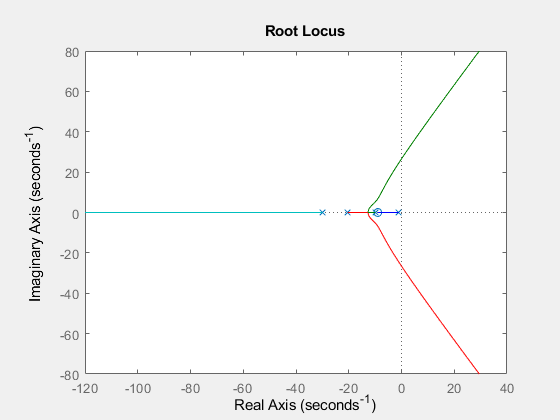

close all;
figure('Name',' Root Locus av G(s) with lead-regulator');
rlocus(system)
set(gcf,'Visible','on');

#### Digitale regulatorar.